# 3D Calibration & Reconstruction Workflow

Written by Yohan Sequeira - 2026

This script walks you through preparing digitized 2D points for a DLT camera calibration, and then using that calibration to reconstruct 3D points. You do NOT need to know MATLAB or DLT to use it — just run one section at a time and pick files when prompted.

**HOW TO USE THIS FILE **

 Run it ONE SECTION AT A TIME using the "Run Section" button, not all at once — there is a manual step in the middle where you compute the DLT calibration in an external program.

**>>> IMPORTANT: CAMERA ORDER <<< **

The camera order MUST be identical everywhere: in the calibration CSV, in the tracked-data CSV, and in the columns of the DLT coefficient file. (i.e. cam1, cam2, cam3 always mean the same physical cameras.) If the orders don't match, reconstruction will silently give WRONG 3D points with no error message.

Overall steps: 

- Load fisheye undistortion parameters (from the calibrator .mat).

- Undistort the calibration points -> save a CSV.

- [OUTSIDE MATLAB] compute the 11 DLT coefficients per camera, using easywand.

- Load the DLT coefficients.

- Load and undistort the tracked points.

- Reconstruct 3D points -> save a CSV.

- Use another script to get the point velocityies/accelerations you need.

Helper functions used: 

loadFisheyeIntrinsics, parseXYptsLayout, undistortUV, undistortPointsTable, reconstruct3D, dltReconstruct.

clear; clc;

cd(fileparts(matlab.desktop.editor.getActiveFilename));
addpath("Helpers\")

## Step 1 — Load fisheye undistortion parameters

Pick the .mat file exported by the MATLAB (single) Camera Calibrator app. All cameras in this rig share the same distortion, so one file covers them all.

(see this for more info about the fisheye: [https://www.mathworks.com/help/vision/ug/fisheye-calibration-basics.html)](https://www.mathworks.com/help/vision/ug/fisheye-calibration-basics.html))

Here, we need the intrinsic fisheye parameters. This can be done by taking a checkerboard of known size, and taking images with it in front of the camera you want the intrinsics of, and then calibrate it using the matlab app. (make sure to export the FISHEYE camera parameters as a .mat file)

[fMat, pMat] = uigetfile({'*.mat','Camera parameters (*.mat)'}, ...
    'Select the fisheye calibration .mat file');
if isequal(fMat, 0); error('No .mat file selected — stopping.'); end

intrinsics = loadFisheyeIntrinsics(fullfile(pMat, fMat));
disp('Loaded fisheye intrinsics:');

Loaded fisheye intrinsics:


disp(intrinsics);

  fisheyeIntrinsics with properties:

    MappingCoefficients: [1.2483e+03 -2.1038e-04 -3.2722e-09 -1.0897e-11]
              ImageSize: [1520 2704]
       DistortionCenter: [1.4058e+03 904.8664]
          StretchMatrix: [2×2 double]



## Step 2 — Undistort the CALIBRATION points

Pick the calibration xypts CSV (DLTdv style: ptP_camC_U / ptP_camC_V). This section undistorts every point and writes a new CSV you will feed to your external DLT program (together with your known wand lengths / world coordinates). Make sure to track the wand across many frames (30-40) across the volume that your 3D motion takes place.

[fCal, pCal] = uigetfile({'*.csv','Calibration points (*.csv)'}, ...
    'Select the CALIBRATION xypts CSV');
if isequal(fCal, 0); error('No calibration CSV selected — stopping.'); end

Tcal   = readtable(fullfile(pCal, fCal), 'VariableNamingRule', 'preserve');
names  = Tcal.Properties.VariableNames;
Mcal   = table2array(Tcal);

[nPtsC, nCamsC] = parseXYptsLayout(names);
fprintf('Calibration file: %d points x %d cameras.\n', nPtsC, nCamsC);

Calibration file: 2 points x 3 cameras.



McalU  = undistortPointsTable(Mcal, nPtsC, nCamsC, intrinsics);

% Save undistorted calibration points, same column names as the input.
[fSave, pSave] = uiputfile('*.csv', 'Save UNDISTORTED calibration points as', ...
    fullfile(pCal, 'Calibration_points_UNDISTORTED.csv'));
if isequal(fSave, 0); error('No save location chosen — stopping.'); end

writetable(array2table(McalU, 'VariableNames', names), fullfile(pSave, fSave));
fprintf('Saved undistorted calibration points to:\n  %s\n', fullfile(pSave, fSave));

Saved undistorted calibration points to:
  C:\Users\yohan\OneDrive\Desktop\Code for Jeff\Test Calibration and Data\Calibration_points_UNDISTORTED.csv


====================================================================

## STOP HERE — do the DLT calibration in easywand

--------------------------------------------------------------------

The easywand calibration toolbox can be found here (with the manual):

(https://biomech.web.unc.edu/easywand6-manual/)

This will need the camera intrinsics (separate from the fisheye intrinsics), which is the image width and height (in pixels) and the camera principal point (the center of the image, so half of the width and height in pixels). You will also need the focal length (in pixels), which you can either get by calibrating the camera (in the same matlab camera app, but not exporting the fisheye parameters, just export the regular camera parameters and then inspect the .mat file for the focal length), or by looking at the value on the lens and converting to pixels. See the images below for a visual explanation: 

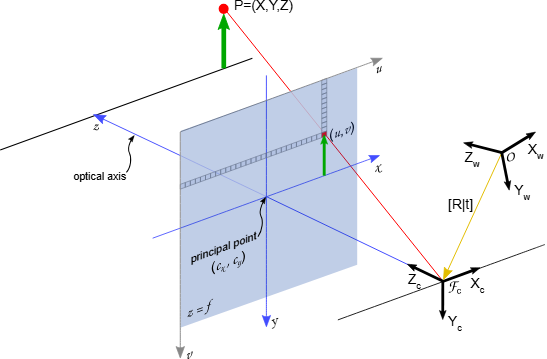

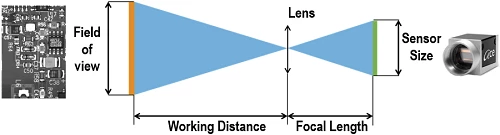

USE this to convert focal length from mm to pixels:

[sensor height (mm) /image height (pix)] == [focal length (mm)/focal length (pix)]

Once you do the calibration in easywand,  Use the undistorted calibration CSV just saved, plus your known wand lengths / world coordinates, to compute the 11 DLT coefficients per camera. Save the result (which is just expprt DLT coeffs option in easywand).

Then continue with Step 3 below.

====================================================================

## Step 3 — Load the DLT coefficients

Pick the CSV your external tool produced (11 rows x nCams columns).

[fDlt, pDlt] = uigetfile({'*.csv','DLT coefficients (*.csv)'}, ...
    'Select the DLT coefficient CSV (11 x nCams)');
if isequal(fDlt, 0); error('No DLT coefficient file selected — stopping.'); end

c = readmatrix(fullfile(pDlt, fDlt));

if size(c,1) ~= 11
    warning(['Expected 11 rows of DLT coefficients but found %d. ', ...
        'dltReconstruct assumes the 12th coefficient = 1 when only 11 are ', ...
        'given.'], size(c,1));
end
fprintf('Loaded DLT coefficients: %d rows x %d cameras.\n', size(c,1), size(c,2));

Loaded DLT coefficients: 11 rows x 3 cameras.


## Step 4 — Load and undistort the TRACKED points

Pick the tracked xypts CSV (same DLTdv layout, same camera order).

[fTrk, pTrk] = uigetfile({'*.csv','Tracked points (*.csv)'}, ...
    'Select the TRACKED xypts CSV');
if isequal(fTrk, 0); error('No tracked CSV selected — stopping.'); end

Ttrk  = readtable(fullfile(pTrk, fTrk), 'VariableNamingRule', 'preserve');
Mtrk  = table2array(Ttrk);

[nPts, nCams] = parseXYptsLayout(Ttrk.Properties.VariableNames);
fprintf('Tracked file: %d points x %d cameras.\n', nPts, nCams);

Tracked file: 6 points x 3 cameras.



if nCams ~= size(c,2)
    error(['Camera count mismatch: tracked data has %d cameras but the DLT ', ...
        'file has %d columns. Check camera order and files.'], nCams, size(c,2));
end

MtrkU = undistortPointsTable(Mtrk, nPts, nCams, intrinsics);

## Step 5 — Reconstruct 3D points and save

Loops over every frame and point. Untracked frames (or frames seen by fewer than 2 cameras) stay NaN so the output remains frame-aligned in time.

XYZ = reconstruct3D(MtrkU, nPts, nCams, c);

% Build wide-format column names mirroring the DLT convention: ptP_X/Y/Z.
xyzNames = cell(1, 3*nPts);
for p = 1:nPts
    xyzNames((p-1)*3 + (1:3)) = {sprintf('pt%d_X',p), sprintf('pt%d_Y',p), sprintf('pt%d_Z',p)};
end

[fXYZ, pXYZ] = uiputfile('*.csv', 'Save reconstructed 3D points as', ...
    fullfile(pTrk, 'Reconstructed_xyzpts.csv'));
if isequal(fXYZ, 0); error('No save location chosen — stopping.'); end

writetable(array2table(XYZ, 'VariableNames', xyzNames), fullfile(pXYZ, fXYZ));
fprintf('Saved reconstructed 3D points to:\n  %s\n', fullfile(pXYZ, fXYZ));

Saved reconstructed 3D points to:
  C:\Users\yohan\OneDrive\Desktop\Code for Jeff\Test Calibration and Data\Reconstructed_xyzpts.csv


## Step 6 — Quick sanity check (optional)

Reports how many frames were reconstructed for each point. If a point has very few frames, check its digitizing / camera coverage.

for p = 1:nPts
    nGood = sum(~isnan(XYZ(:, (p-1)*3 + 1)));
    fprintf('pt%d: %d of %d frames reconstructed.\n', p, nGood, size(XYZ,1));
end

pt1: 26 of 221981 frames reconstructed.
pt2: 26 of 221981 frames reconstructed.
pt3: 26 of 221981 frames reconstructed.
pt4: 26 of 221981 frames reconstructed.
pt5: 25 of 221981 frames reconstructed.
pt6: 25 of 221981 frames reconstructed.


For final steps, you can use the gravity_align_points.m file to align your points to a vertical axis (plumb line) that you have tracked in your scene. Otherwise, you should be good to go!